`Erfan Panahi   810198369`

## `Wireless Cimmunication`

# `Computer Assignement 1`

# `Part 1. ``Channel effects on the received power`

### 
$$:\ldotp d~\textrm{Uniform}\left\lbrack d_0 \;,D\right\rbrack$$


clc
clear
close all

`Definitions:`

d0 = 10; % minimum distance
D = 1e3; % maximum distance
n = 4; % Simplified pathloss parameter
N0_dBm = -175; % Spectral density of white gausian noise (dBm)
N0 = 10 ^ ((N0_dBm - 30)/10); % Spectral density of white gausian noise (Linear)
num_users = 1e5; % Number of users
B = 1e6; % Bandwidth of signal
Pr_avg = 1e-6; % Average recieved power at d = d0

### `Part a. ``Plotting the CDF of received power`

dist = (D-d0) * rand(num_users, 1) + d0;
P0_dBm = 10 * log10(Pr_avg) + 30;


$$P_r^{\;\textrm{dBm}} =P_0^{\;\textrm{dBm}} -10n\log \left(\frac{d}{d_0 }\right)$$


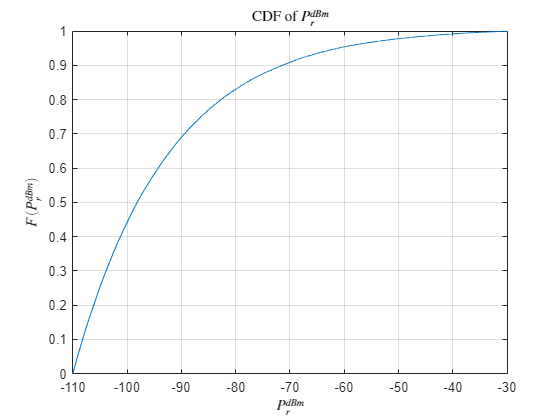

Pr_dBm = P0_dBm - 10*n*log10(dist / d0);
cdfplot(Pr_dBm)
xlabel('$P_r^{dBm}$','Interpreter','latex')
ylabel('$F(P_r^{dBm})$','Interpreter','latex')
title('CDF of $P_r^{dBm}$','Interpreter','latex')

### `Part b. Plotting the SNR per distance of users`

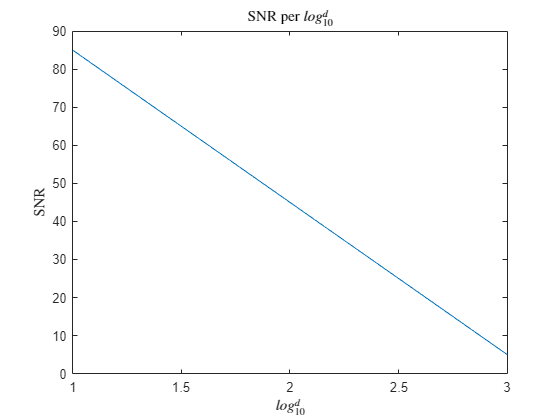

Pn = N0 * B;
Pn_dBm = 10 * log10(Pn) + 30;
SNR = Pr_dBm - Pn_dBm;
[dist_sorted, ind] = sort(dist);
SNR_sorted = SNR(ind);
plot(log10(dist_sorted), SNR_sorted)
xlabel('$log_{10}^{d}$','Interpreter','latex')
ylabel('SNR','Interpreter','latex')
title('SNR per $log_{10}^{d}$','Interpreter','latex')

### `Part c. Considering the shadowing effect`

- `Definition of gaussian normal distribiution (Shadowing): `

sigma_dB = 5;
sigma = 10^(sigma_dB/10);
X = sigma * randn(num_users, 1);

- `Plotting the CDF of received power (with considering the shadowing effect):`


$$P_r^{\;\textrm{dBm}} =P_0^{\;\textrm{dBm}} -10n\log \left(\frac{d}{d_0 }\right)+X^{\textrm{dBm}}$$


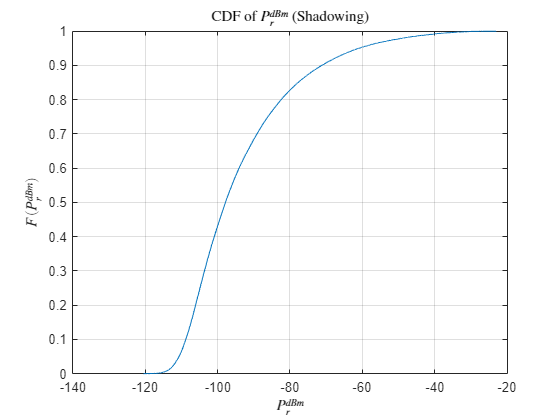

Pr_dBm_sh = P0_dBm - 10*n*log10(dist / d0) + X;
cdfplot(Pr_dBm_sh)
xlabel('$P_r^{dBm}$','Interpreter','latex')
ylabel('$F(P_r^{dBm})$','Interpreter','latex')
title('CDF of $P_r^{dBm}$ (Shadowing)','Interpreter','latex')

- `Plotting the SNR per distance of users (with considering the shadowing effect):`

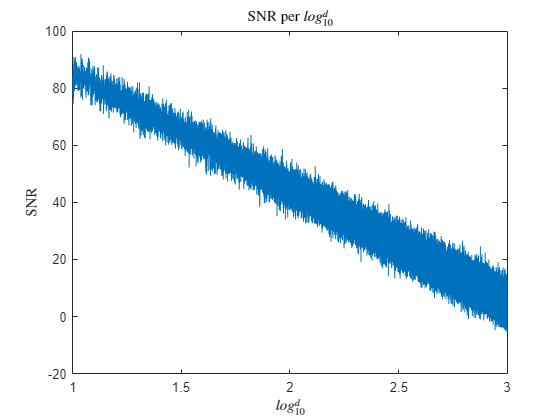

SNR_sh = Pr_dBm_sh - Pn_dBm;
[dist_sorted, ind] = sort(dist);
SNR_sh_sorted = SNR_sh(ind);
plot(log10(dist_sorted), SNR_sh_sorted)
xlabel('$log_{10}^{d}$','Interpreter','latex')
ylabel('SNR','Interpreter','latex')
title('SNR per $log_{10}^{d}$','Interpreter','latex')

### `Part d. ``Plotting the outage probaiblity per distance of users`


$$\textrm{SNR}=P_r^{\;\textrm{dBm}} -P_n^{\;\textrm{dBm}}$$



$$\begin{array}{l}
P_{\textrm{out}} =\Pr \left(\textrm{SNR}<{\textrm{SNR}}_{\min } \right)=\Pr \left(P_r^{\;\textrm{dBm}} -P_n^{\;\textrm{dBm}} <{\textrm{SNR}}_{\min } \right)=\Pr \left(P_0^{\;\textrm{dBm}} -10n\log \left(\frac{d}{d_0 }\right)+X^{\textrm{dBm}} -P_n^{\;\textrm{dBm}} <{\textrm{SNR}}_{\min } \right)=\Pr \left(X^{\textrm{dBm}} <P_n^{\;\textrm{dBm}} +10n\log \left(\frac{d}{d_0 }\right)+{\textrm{SNR}}_{\min } -P_0^{\;\textrm{dBm}} \right)\\
\to P_{\textrm{out}} =Q\left(P_0^{\;\textrm{dBm}} -{\textrm{SNR}}_{\min } -P_n^{\;\textrm{dBm}} -10n\log \left(\frac{d}{d_0 }\right)\right)
\end{array}$$


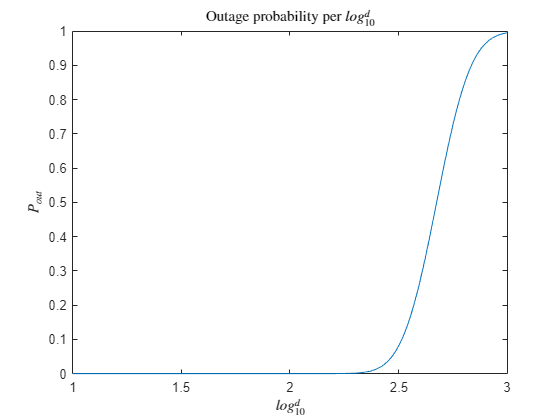

SNR_min = 18;
P_out = qfunc((P0_dBm - SNR_min - Pn_dBm - 10*n*log10(dist_sorted/d0)) / (sigma_dB));
plot(log10(dist_sorted), P_out)
xlabel('$log_{10}^{d}$','Interpreter','latex')
ylabel('$P_{out}$','Interpreter','latex')
title('Outage probability per $log_{10}^{d}$','Interpreter','latex')

### `Part e. ``Coverage Area`

- `Simulaiontion:`

[~, index_d] = max(find(SNR > SNR_min));
d_cover = dist_sorted(index_d);
S_simulation = pi*(d_cover^2-d0^2)

S_simulation = 7.0295e+05

C_simulation = S_simulation / (pi*D^2) 

C_simulation = 0.2238

- `Theorical Solution:`


$$C=Q\left(a\right)+\exp \left(\frac{2-2\textrm{ab}}{b^2 \;}\right)Q\left(\frac{2-\textrm{ab}}{\;b}\right)\to a=\frac{P_{r,\min } -P_r \left(D\right)}{\sigma \;}\;\;,\;b=\frac{10{\textrm{nlog}}_{10} \left(e\right)}{\sigma \;}$$



$$P_r \left(D\right)=P_0 -10{\textrm{nlog}}_{10} \left(\frac{D}{d_0 }\right)$$



$$S=\pi \;D^2 C$$


Pr_D = P0_dBm - 30 - 10*n*log10(D/d0);
Pr_min = SNR_min + Pn_dBm - 30;
a = (Pr_min - Pr_D) / sigma_dB;
b = 10*n*log10(exp(1)) / sigma_dB;
C = qfunc(a) + exp((2-2*a*b)/b^2)*qfunc((2-a*b)/b);
S_theorical = pi*D^2*C

S_theorical = 8.2688e+05

C_theorical = C

C_theorical = 0.2632

### 
$$:\ldotp X~\textrm{Uniform}\left\lbrack d_0 \;,D\right\rbrack ,\;Y~\textrm{Uniform}\left\lbrack d_0 \;,D\right\rbrack \to d_{0\;} \le d=\sqrt{\;X^2 +Y^{2\;} }\le D$$


clc
clear
close all

`Definitions:`

d0 = 10; % minimum distance
D = 1e3; % maximum distance
n = 4; % Simplified pathloss parameter
N0_dBm = -175; % Spectral density of white gausian noise (dBm)
N0 = 10 ^ ((N0_dBm - 30)/10); % Spectral density of white gausian noise (Linear)
num_users = 1e5; % Number of users
B = 1e6; % Bandwidth of signal
Pr_avg = 1e-6; % Average recieved power at d = d0

### `Part a. ``Plotting the CDF of received power`

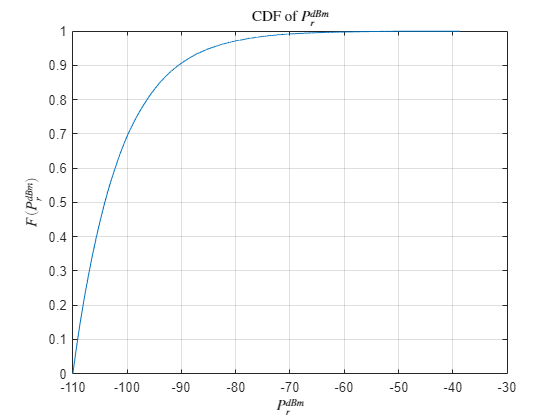

X = (D-d0) * rand(num_users, 1) + d0;
Y = (D-d0) * rand(num_users, 1) + d0;
dist = sqrt(X.^2 + Y.^2);
while(1)
    NC = find(dist > D);
    if (isempty(NC)) 
        break 
    end
    x = (D-d0) * rand(length(NC), 1) + d0;
    y = (D-d0) * rand(length(NC), 1) + d0;
    dist(NC) = sqrt(x.^2 + y.^2);
end
P0_dBm = 10 * log10(Pr_avg) + 30;
Pr_dBm = P0_dBm - 10*n*log10(dist / d0);
cdfplot(Pr_dBm)
xlabel('$P_r^{dBm}$','Interpreter','latex')
ylabel('$F(P_r^{dBm})$','Interpreter','latex')
title('CDF of $P_r^{dBm}$','Interpreter','latex')

### `Part b. Plotting the SNR per distance of users`

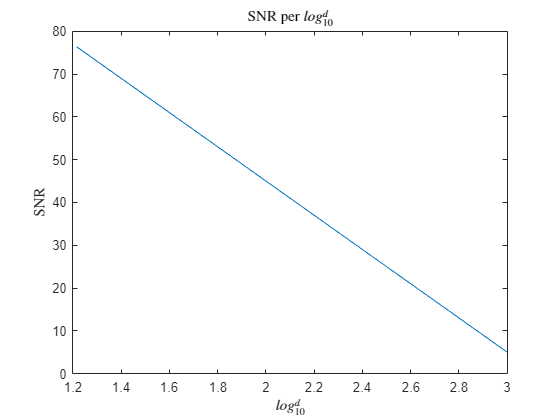

Pn = N0 * B;
Pn_dBm = 10 * log10(Pn) + 30;
SNR = Pr_dBm - Pn_dBm;
[dist_sorted, ind] = sort(dist);
SNR_sorted = SNR(ind);
plot(log10(dist_sorted), SNR_sorted)
xlabel('$log_{10}^{d}$','Interpreter','latex')
ylabel('SNR','Interpreter','latex')
title('SNR per $log_{10}^{d}$','Interpreter','latex')

### `Part c. Considering the shadowing effect`

- `Definition of gaussian normal distribiution (Shadowing): `

sigma_dB = 5;
sigma = 10^(sigma_dB/10);
X = sigma * randn(num_users, 1);

- `Plotting the CDF of received power (with considering the shadowing effect):`

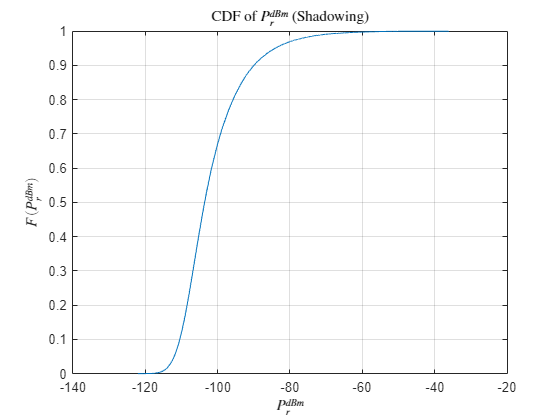

Pr_dBm_sh = P0_dBm - 10*n*log10(dist / d0) + X;
cdfplot(Pr_dBm_sh)
xlabel('$P_r^{dBm}$','Interpreter','latex')
ylabel('$F(P_r^{dBm})$','Interpreter','latex')
title('CDF of $P_r^{dBm}$ (Shadowing)','Interpreter','latex')

- `Plotting the SNR per distance of users (with considering the shadowing effect):`

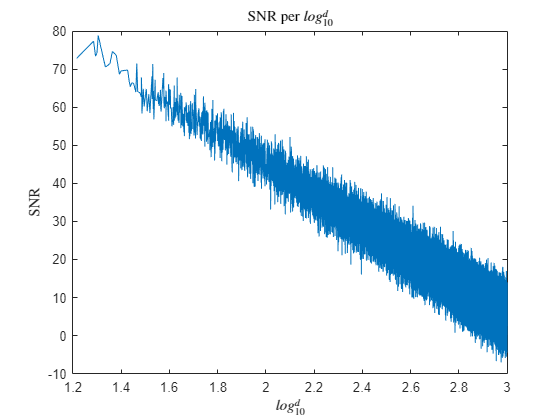

SNR_sh = Pr_dBm_sh - Pn_dBm;
[dist_sorted, ind] = sort(dist);
SNR_sh_sorted = SNR_sh(ind);
plot(log10(dist_sorted), SNR_sh_sorted)
xlabel('$log_{10}^{d}$','Interpreter','latex')
ylabel('SNR','Interpreter','latex')
title('SNR per $log_{10}^{d}$','Interpreter','latex')

### `Part d. ``Plotting the outage probaiblity per distance of users`

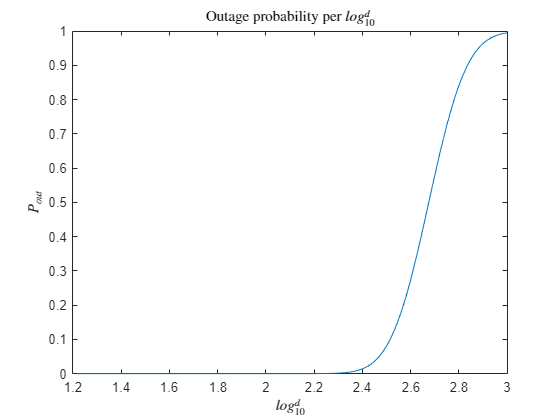

SNR_min = 18;
P_out = qfunc((P0_dBm - SNR_min - Pn_dBm - 10*n*log10(dist_sorted/d0)) / (sigma_dB));
plot(log10(dist_sorted), P_out)
xlabel('$log_{10}^{d}$','Interpreter','latex')
ylabel('$P_{out}$','Interpreter','latex')
title('Outage probability per $log_{10}^{d}$','Interpreter','latex')

### `Part e. ``Coverage Area`

- `Simulaiontion:`

[~, index_d] = max(find(SNR > SNR_min));
d_cover = dist_sorted(index_d);
S_simulation = pi*(d_cover^2-d0^2)

S_simulation = 7.0296e+05

C_simulation = S_simulation / (pi*D^2) 

C_simulation = 0.2238

- `Theorical Solution:`

Pr_D = P0_dBm - 30 - 10*n*log10(D/d0);
Pr_min = SNR_min + Pn_dBm - 30;
a = (Pr_min - Pr_D) / sigma_dB;
b = 10*n*log10(exp(1))/sigma_dB;
C = qfunc(a) + exp((2-2*a*b)/b^2)*qfunc((2-a*b)/b);
S_theorical = pi*D^2*C

S_theorical = 8.2688e+05

C_theorical = C

C_theorical = 0.2632

# `Part 2. ``Multipath Wireless Channel  `

clc
clear
close all

`Definitions:`

N = 15; % Number of paths 
Tetha = rand(N, 1) * pi/2; % Angle of each path
Tau = 9e-6 * rand(N, 1) + 1e-6; % Random delay of each path
Power_avg = 1e-3 * (Tau*1e6).^-4; % Average power of each path
sigma = sqrt(Power_avg/2); 
Alpha = raylrnd(sigma); 
v = 30; % Velocity of a mobile user
fc = 3e9; % Frequency of carrier
lambda = 3e8 / fc;

### `Part a:`

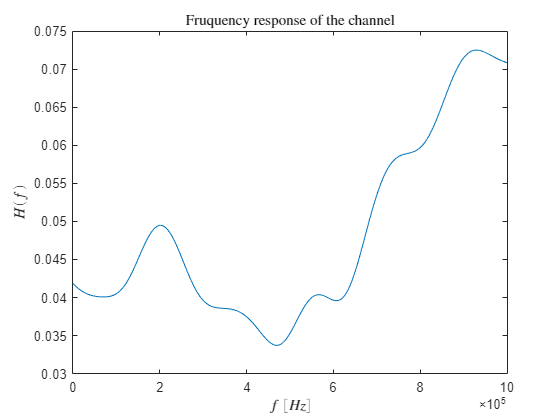

f_D = v / lambda * cos(Tetha); % Doppler frequency
Phi = 2 * pi * (fc - f_D) .* Tau; % Pahse shift
f = 0:1e6;
R = (Alpha .* exp(-1i*Phi)).' * exp(-1i*2*pi*Tau*f);
figure
plot(f, abs(R));
xlabel('$f$ $[Hz]$','Interpreter','latex')
ylabel('$H(f)$','Interpreter','latex')
title('Fruquency response of the channel','Interpreter','latex')

### `Part b:`

repeat_num = 1e5;
h2 = [];
for i = 1:repeat_num
    Tetha = rand(N, 1) * pi/2;
    Tau = 9e-6 * rand(N, 1) + 1e-6;
    Power_avg = 1e-3 * (Tau*1e6).^-4;
    sigma = sqrt(Power_avg/2);
    Alpha = raylrnd(sigma);
    f_D = v / lambda * cos(Tetha);
    h = Alpha .* exp(1i*2*pi*f_D.*Tau) .* exp(-1i*2*pi*fc*Tau);
    h2 = [h2; sum(abs(h).^2)];
end
E_h2 = mean(h2)

E_h2 = 5.5623e-04

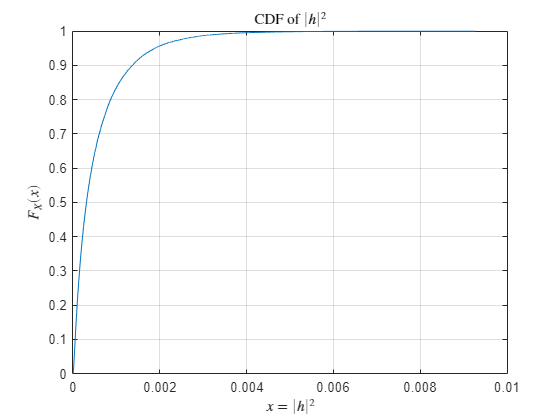

figure
cdfplot(h2);
xlabel('$x=|h|^2$','Interpreter','latex')
ylabel('$F_X(x)$','Interpreter','latex')
title('CDF of $|h|^2$','Interpreter','latex')

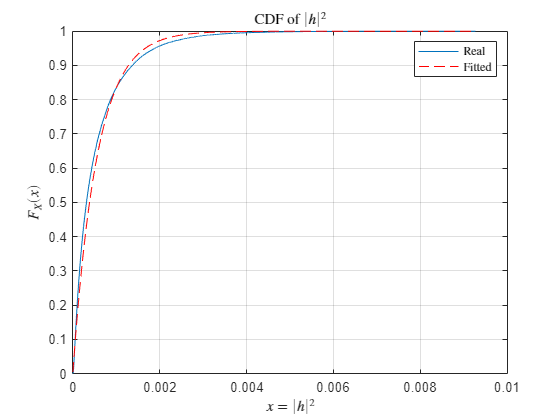

figure
cdfplot(h2);
hold on
plot(sort(h2), 1-exp(-sort(h2)/E_h2), 'r--');
xlabel('$x=|h|^2$','Interpreter','latex')
ylabel('$F_X(x)$','Interpreter','latex')
title('CDF of $|h|^2$','Interpreter','latex')
legend('Real', 'Fitted', 'Interpreter', 'latex')
hold off